# Panel models with cross sections

Tutorial file for testing panel models

## Housekeeping

clear
close all
clear classes

rehash path

import cross.*  


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all cross-section panel BVAR models, regardless of the specific estimator used.

The properties are as follows:

**endogenousConcepts **–  a list of endogenous variables, listed without the country suffix. Plays the same role as **endogenousNames** in plain BVARs

**units **– a list of countries/units that share the same endogenous variables


estimStart = datex("1972-Q1");
estimEnd = datex("2014-Q4");
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousConcepts=["YER", "HICSA", "STN"], ...
    units=["US", "EA", "UK"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);



## Specifying and loading input data


inputTbl = tablex.fromFile("panelData.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

There are some common properties for the cross section panel BVARs. Which are

**Alpha0 (1000)** – The shape of the Inverse Gamma distribution of residual variances

**Delta0 (1)** – The scale of the Inverse Gamma distribution of residual variances

#### Static Cross Panel

estimatorR1 = estimator.StaticCrossPanel(meta);

#### Dynamic Cross Panel

**A0 (1000)** – The shape of the Inverse Gamma distribution of factor variances

**B0 (1)** – The scale of the Inverse Gamma distribution of factor variances

**Rho (0.75)** – The AR coefficient in the prior for factor coefficients.

**Gamma (0.85)** – The AR coefficient for latent innovation series

% estimatorR1 = estimator.DynamicCrossPanel(meta);

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.2281
    0.1701
    0.1701
    0.1670
    0.1090
    0.1090
    0.1670
    0.1090
    0.1090
    0.0057


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

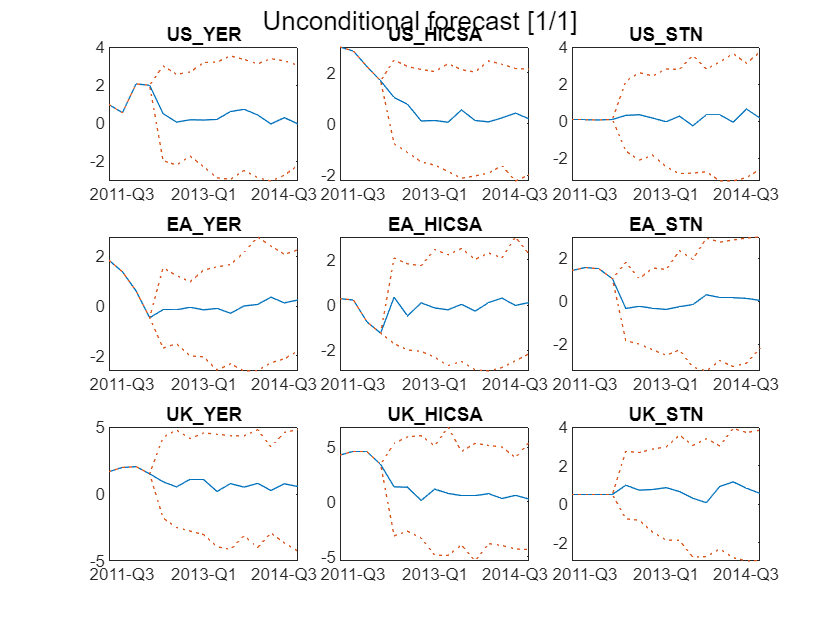

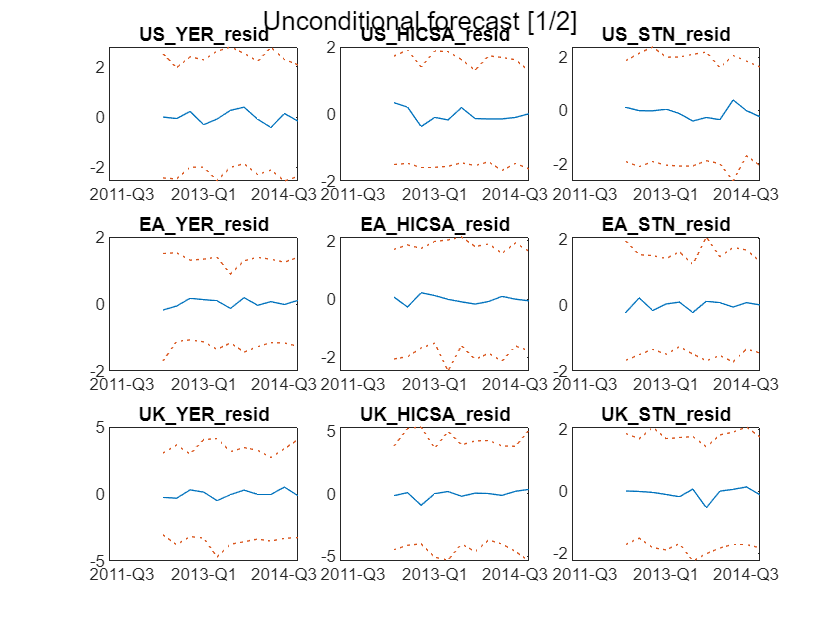

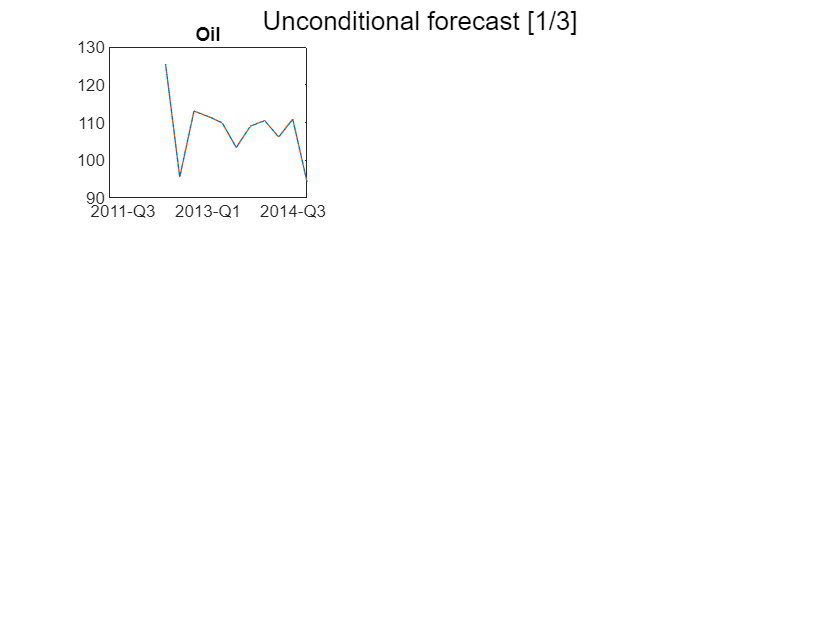

ans = 1×3 cell array
    {1×1 Figure}    {1×1 Figure}    {1×1 Figure}



chartpack.forecastPercentiles( ...
    fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")


## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [342×1 double]
                 sigma: [81×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [9×9 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [9×9 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.2151    0.1542    0.1542    0.1610    0.1001    0.1001    0.1610    0.1001    0.1001
    0.1542    0.2181    0.1542    0.1001    0.1640    0.1001    0.1001    0.1640    0.1001
    0.1542    0.1542    0.2268    0.1001    0.1001    0.1727    0.1001    0.1001    0.1727
    0.1610    0.1001    0.1001    0.2181    0.1572    0.1572    0.1610    0.1001    0.1001
    0.1001    0.1640    0.1001    0.1572    0.2211    0.1572    0.1001    0.1640    0.1001
    0.1001    0.1001    0.1727    0.1572    0.1572    0.2298    0.1001    0.1001    0.1727
    0.1610    0.1001    0.1001    0.1610    0.1001    0.1001    0.2243    0.1634    0.1634
    0.1001    0.1640    0.1001    0.1001    0.1640    0.1001    0.1634    0.2273    0.1634
    0.1001    0.1001    0.1727    0.1001    0.1001    0.1727    0.1634    0.1634    0.2361
    0.0194   -0.0415   -0.0415   -0.0347   -0.0956   -0.0956   -0.0347   -0.0956   -0.0956


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.2151    0.1542    0.1542    0.1610    0.1001    0.1001    0.1610    0.1001    0.1001
    0.1542    0.2181    0.1542    0.1001    0.1640    0.1001    0.1001    0.1640    0.1001
    0.1542    0.1542    0.2268    0.1001    0.1001    0.1727    0.1001    0.1001    0.1727
    0.1610    0.1001    0.1001    0.2181    0.1572    0.1572    0.1610    0.1001    0.1001
    0.1001    0.1640    0.1001    0.1572    0.2211    0.1572    0.1001    0.1640    0.1001
    0.1001    0.1001    0.1727    0.1572    0.1572    0.2298    0.1001    0.1001    0.1727
    0.1610    0.1001    0.1001    0.1610    0.1001    0.1001    0.2243    0.1634    0.1634
    0.1001    0.1640    0.1001    0.1001    0.1640    0.1001    0.1634    0.2273    0.1634
    0.1001    0.1001    0.1727    0.1001    0.1001    0.1727    0.1634    0.1634    0.2361
    0.0194   -0.0415   -0.0415   -0.0347   -0.0956   -0.0956   -0.0347   -0.0956   -0.0956


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     1.5540   -0.4064   -0.4006    0.1699   -0.1204    0.1405    0.4617   -0.3577   -0.4552
         0    0.9019    0.0929   -0.3617   -0.3869    0.3547   -0.3506    0.3256    0.0357
         0         0    1.2687    0.0795    0.1526    0.0239    0.0314   -0.2259    0.1305
         0         0         0    0.9485   -0.5991    0.2529   -0.6214    0.6570    0.1718
         0         0         0         0    1.4823   -0.8167    1.0219   -1.2769    0.2525
         0         0         0         0         0    0.7445    0.2267   -0.3233    0.0564
         0         0         0         0         0         0    1.3035   -0.4377   -0.2623
         0         0         0         0         0         0         0    1.3019   -0.0856
         0         0         0         0         0         0         0         0    0.9705


modelS1.Presampled{2}.D

ans =     1.3658   -0.3650   -0.3302    0.0866   -0.1168    0.1416    0.3195   -0.2674   -0.5678
         0    0.8940    0.1567   -0.2610   -0.5792    0.3219   -0.6158    0.8947   -0.0951
         0         0    1.0670    0.1735    0.1003    0.0530    0.1243   -0.3019    0.1172
         0         0         0    0.8146   -0.4695    0.1982   -0.5818    1.0529    0.2062
         0         0         0         0    1.2955   -0.6136    1.2359   -1.2800    0.3002
         0         0         0         0         0    0.6493    0.2616   -0.6098    0.1392
         0         0         0         0         0         0    1.3626   -0.6177   -0.2782
         0         0         0         0         0         0         0    1.3640   -0.1028
         0         0         0         0         0         0         0         0    0.8839


## Impulse respones (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();
respTbl1 = tablex.apply(respTbl1, prctileFunc);


  (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.flatten(respTbl1);

respTbl1


respTbl1 = 24×81 timetable
     Time                 US_YER___US_DEM                           US_YER___US_SUP                        US_YER___US_POL                        US_YER___EA_DEM                           US_YER___EA_SUP                        US_YER___EA_POL                       US_YER___UK_DEM                        US_YER___UK_SUP                      US_YER___UK_POL                       US_HICSA___US_DEM                      US_HICSA___US_SUP                   US_HICSA___US_POL                      US_HICSA___EA_DEM                          US_HICSA___EA_SUP                         US_HICSA___EA_POL                        US_HICSA___UK_DEM                          US_HICSA___UK_

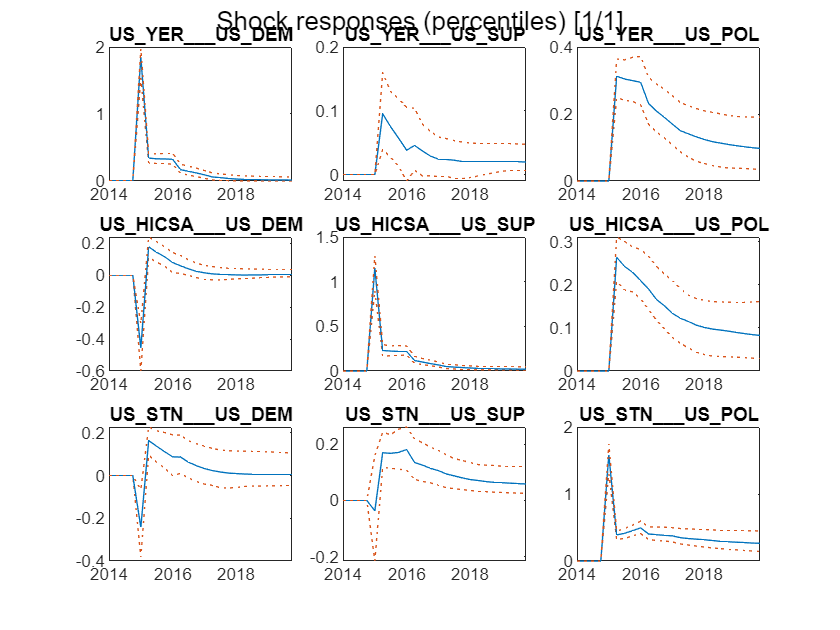

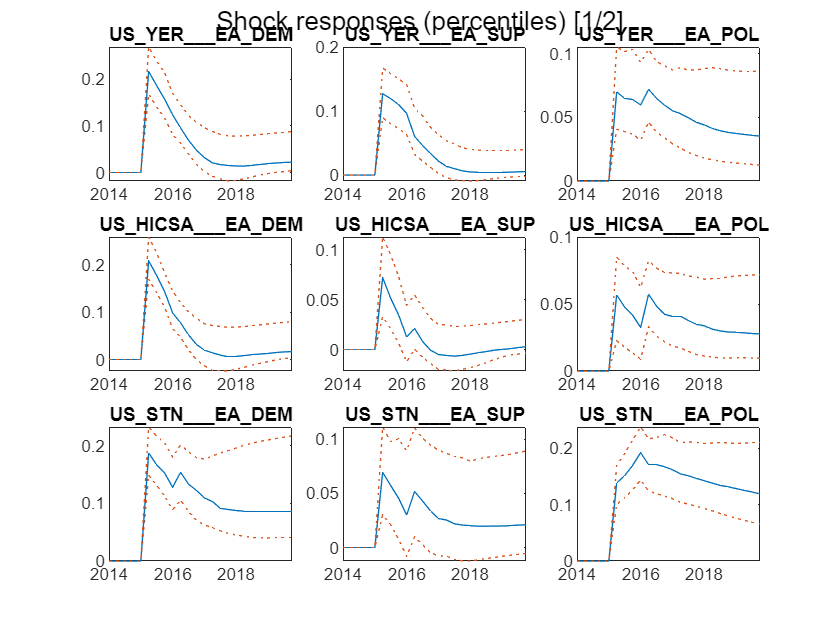

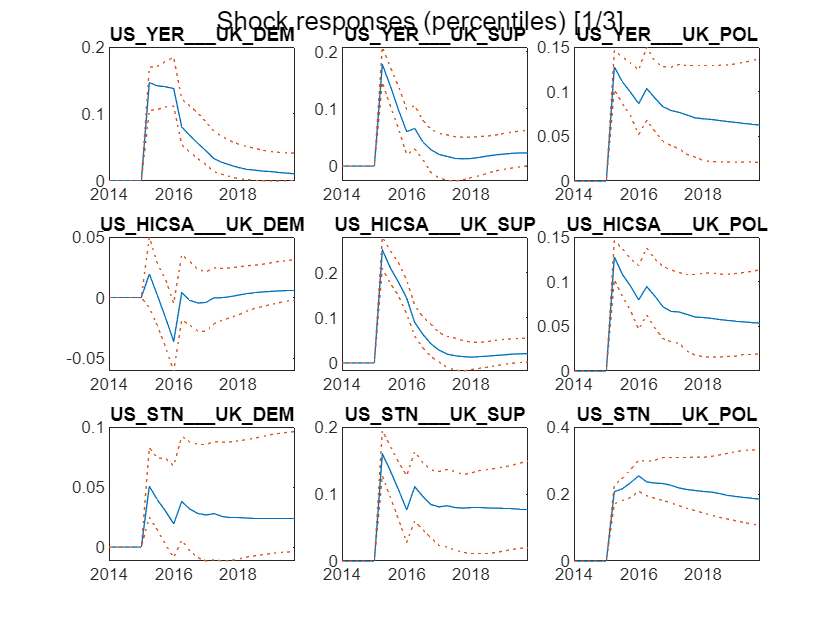

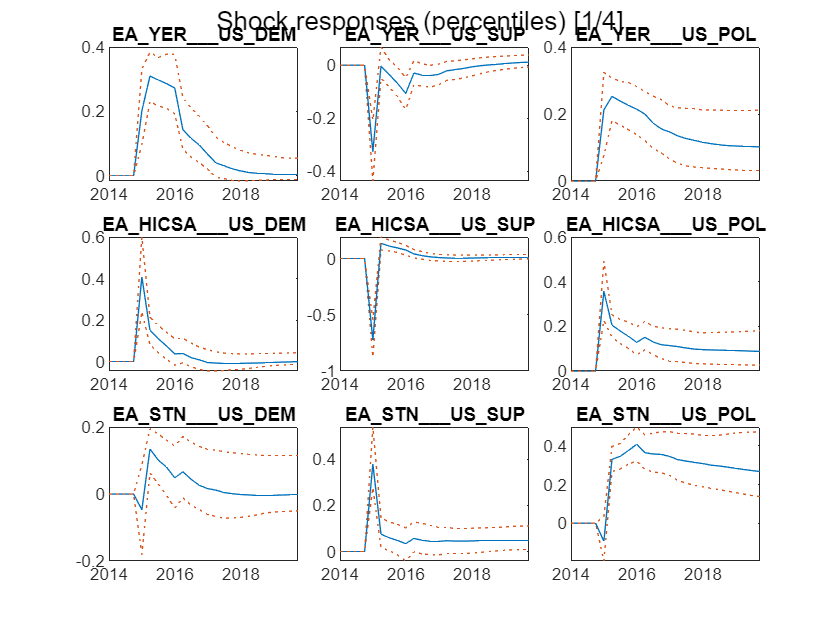

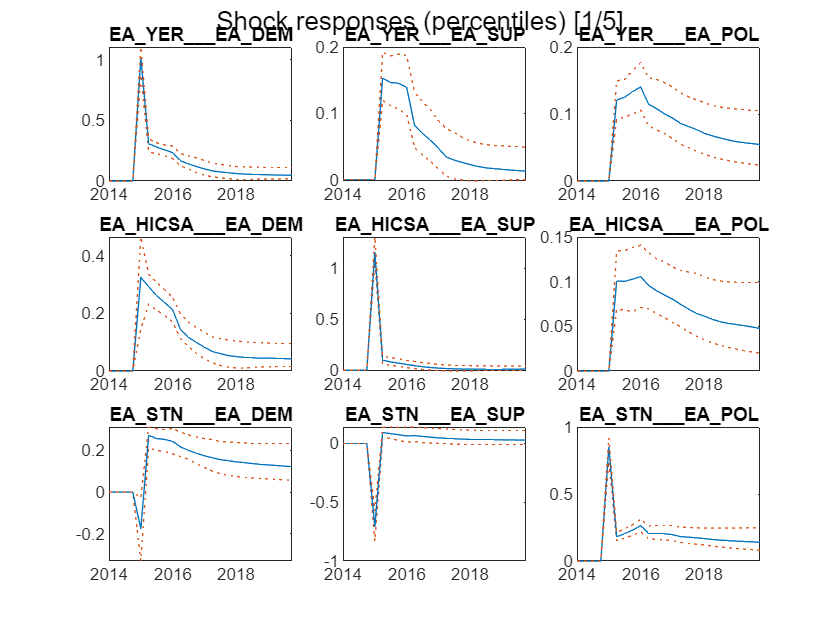

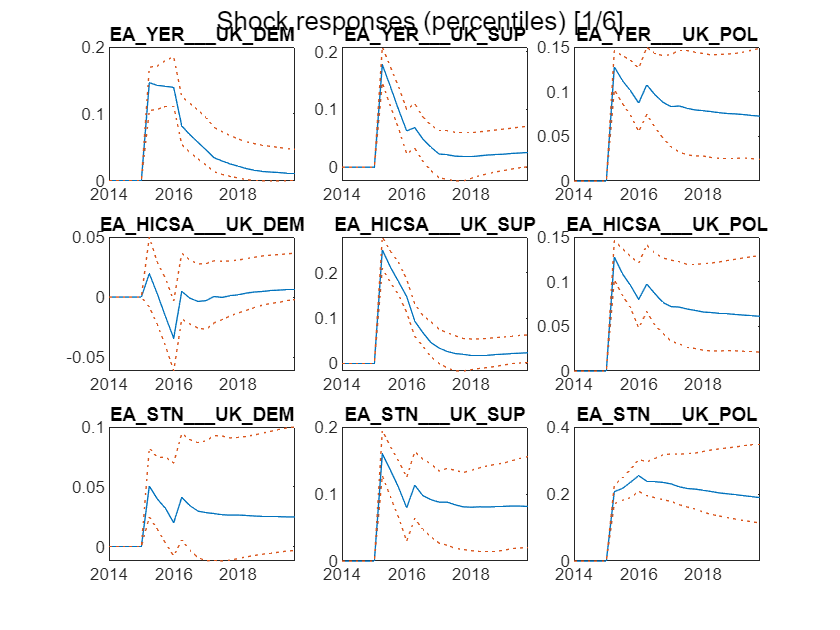

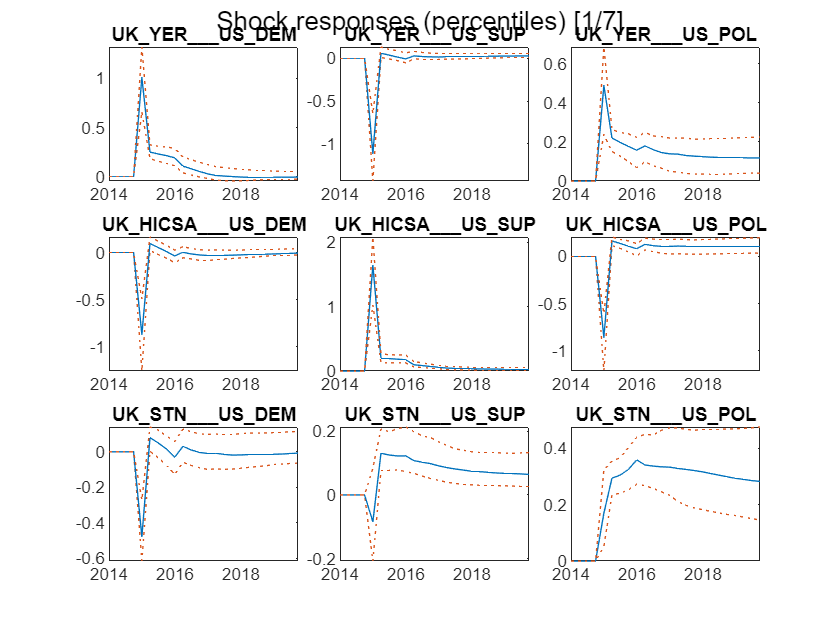

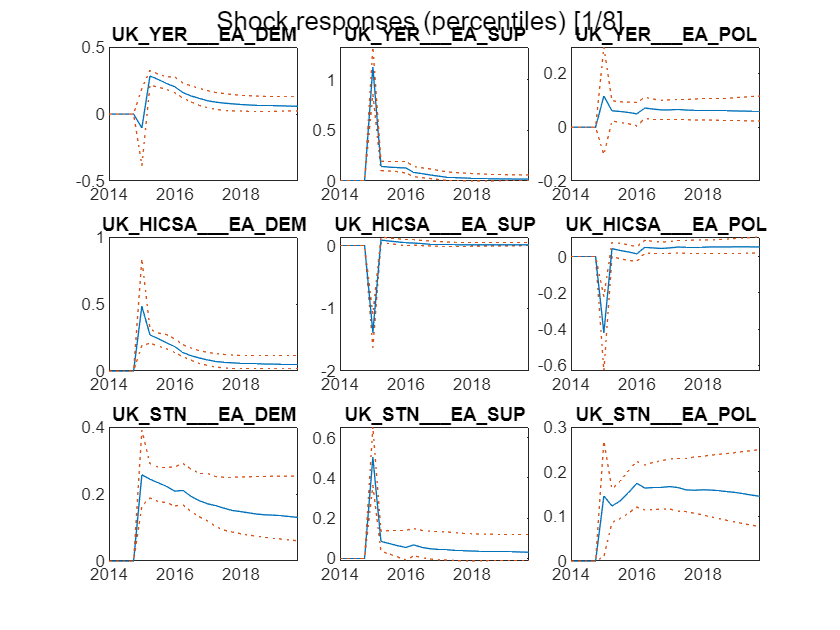

chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock responses (percentiles)" ...
);

## **Historical shock decomposition**


histContTbx = modelS1.calculateContributions();

tablex.getHigherDims(histContTbx)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"    "Exogenous"    "Initials"]}


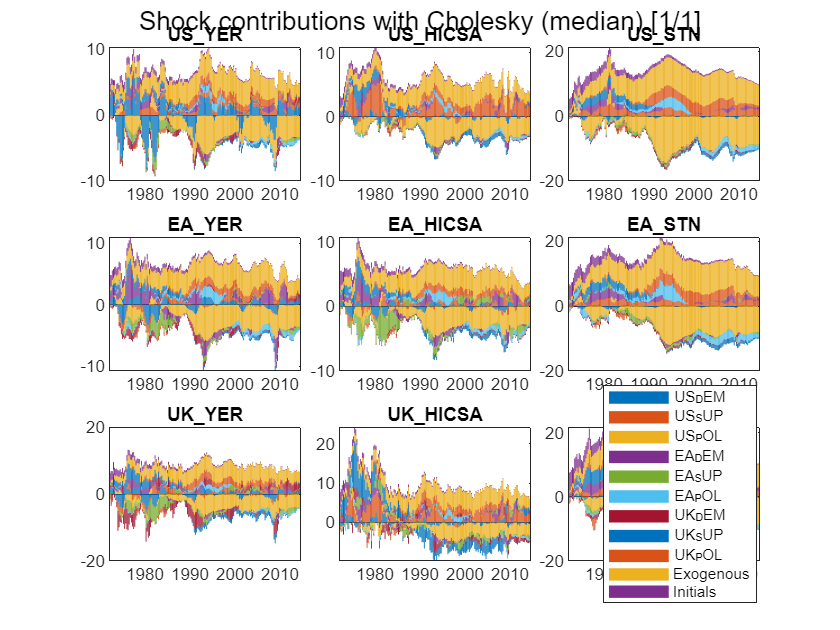


histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS1 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"    "Exogenous"    "Initials"]}


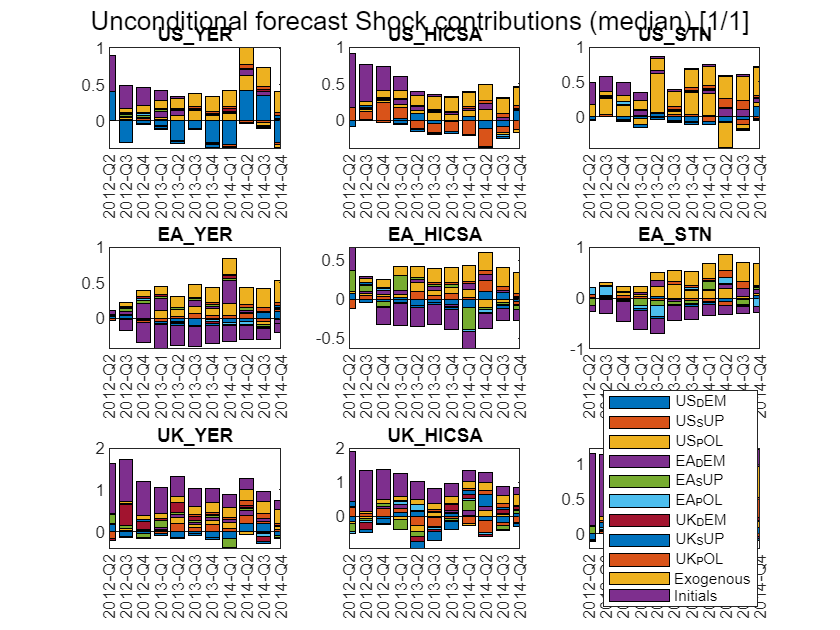


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);
contMedTbx = tablex.apply(contMedTbx, flatFunc);

chartpack.contributionsMedian( ...
    contMedTbx,modelS1 ...
    , "figureTitle", "Unconditional forecast Shock contributions (median)" ...
);

## **FEVD**


fevdTbx = modelS1.calculateFEVD();


  (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




tablex.getHigherDims(fevdTbx)

ans = 1×1 cell array
    {["US_DEM"    "US_SUP"    "US_POL"    "EA_DEM"    "EA_SUP"    "EA_POL"    "UK_DEM"    "UK_SUP"    "UK_POL"]}


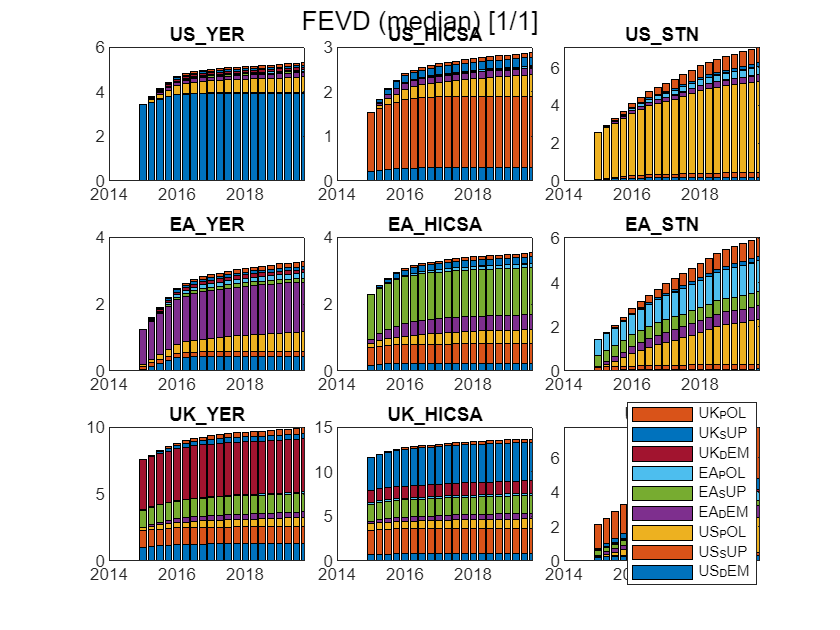


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);
fevdMedTbx = tablex.apply(fevdMedTbx, flatFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx,modelS1 ...
    , "figureTitle", "FEVD (median)" ...
);

## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTblPanel.xlsx");
planTbl = tablex.readConditioningPlan("planTblPanel.xlsx");

### Settig up the forecast range 

cfcastStart = datex.shift(modelR1.Meta.EstimationEnd, 1); %The forecast starts after the estimation span.
cfcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 12); 
cfcastSpan = datex.span(cfcastStart, cfcastEnd);

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

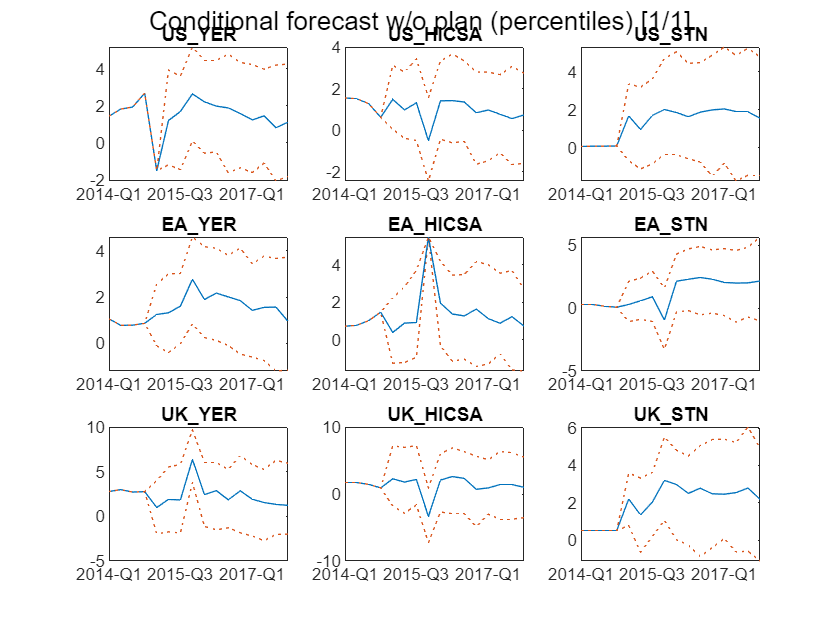

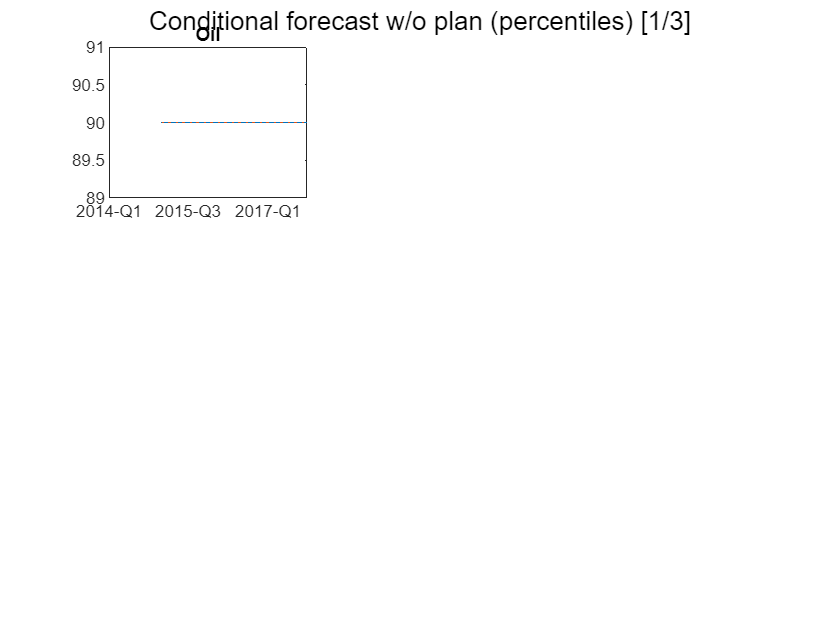

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl1,modelS1 ...
    , "figureTitle", "Conditional forecast w/o plan (percentiles)" ...
);

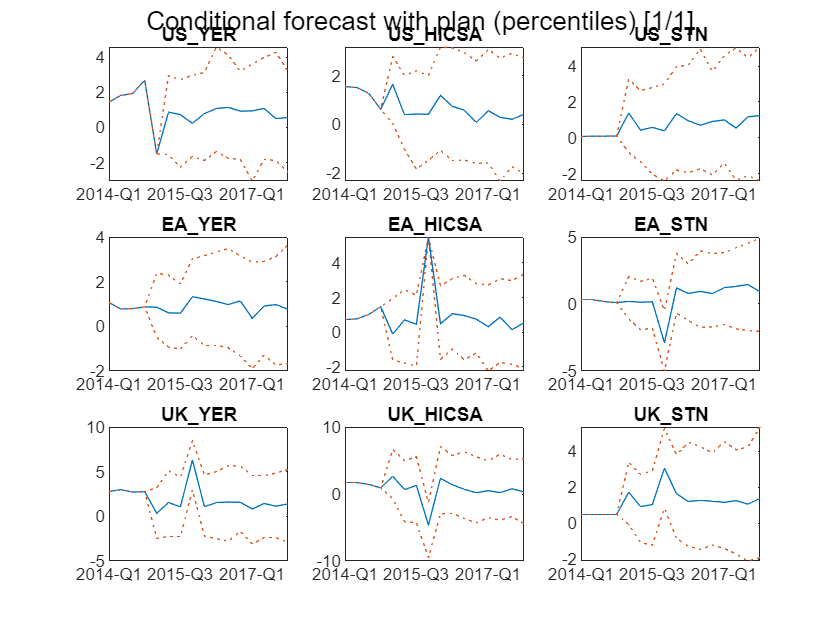

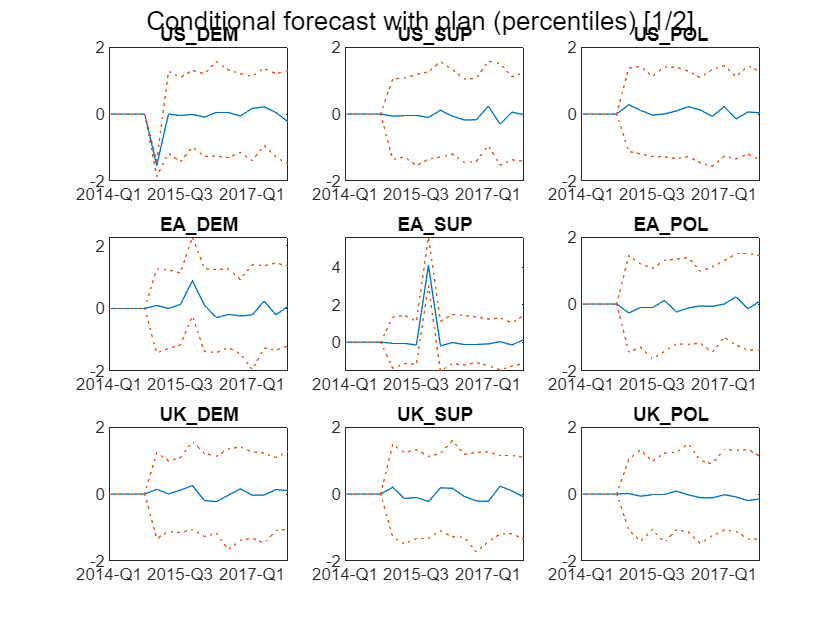

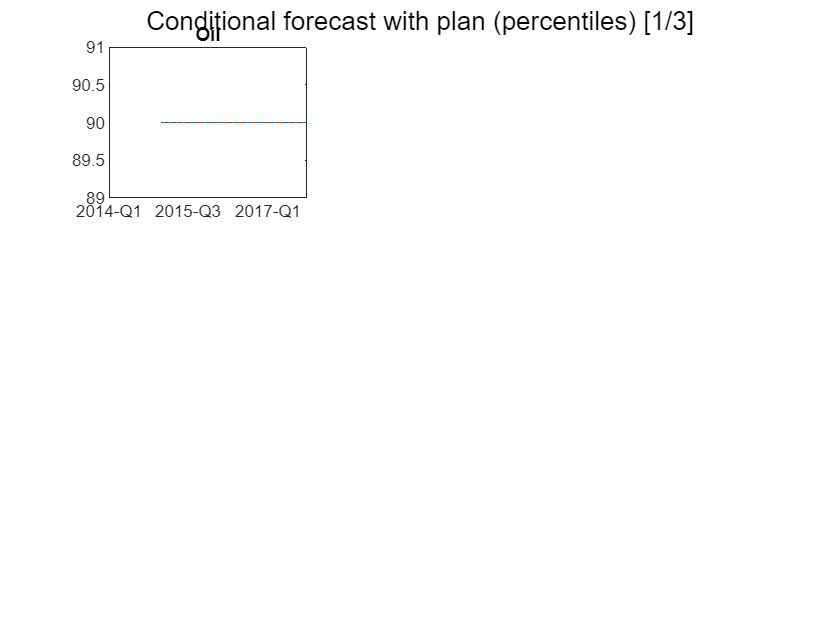


chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl2,modelS1 ...
    , "figureTitle", "Conditional forecast with plan (percentiles)" ...
);